# FPGA计算结果同MATLAB仿真结果对比

## 全局参数设置

clc,clear all

% 全局参数设置
tspan =1:1000;
Tlen =length(tspan);
signal=zeros(Tlen,1);
alpha  = 1;     % 序列扩大倍数
figstart = 100;   % 图像绘制时从第100个混沌信号开始

## step1 MATLAB计算混沌序列

混沌系统模型如下：

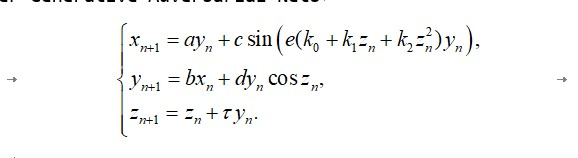

去6组不同的参数或初值，得到6组不同的混沌序列

% step: 1.1 混沌方程参数与初值设置
f1_parameter = [1.2,0.1,-1.2,1.6,pi/6,0.3,0.1,-10,0.5];
f1_x0 = [0.5,0.5,0.1];
f2_parameter = [1.2,0.1,-1.2,1.6,pi/6,0.3,0.1,-10,0.5];
f2_x0 = [0.55,0.5,0.1];
f3_parameter = [1.2,0.1,-1.2,1.6,pi/6,0.3,0.1,-10,0.5];
f3_x0 = [0.6,0.5,0.1];
f4_parameter = [1.2,0.1,-1.2,1.6,pi/6,0.3,0.1,-10,0.5];
f4_x0 = [0.65,0.5,0.1];
f5_parameter = [1.2,0.1,-1.2,1.6,pi/6,0.3,0.1,-10,0.5];
f5_x0 = [0.69,0.5,0.1];
f6_parameter = [1.2,0.1,-1.2,1.6,pi/6,0.3,0.1,-10,0.5];
f6_x0 = [0.73,0.5,0.1];

% step: 1.2 MATLAB计算混沌序列
MATLAB_f1_out =(ChaosMapInteg(f1_parameter,tspan,f1_x0))*alpha;
MATLAB_f2_out =(ChaosMapInteg(f2_parameter,tspan,f2_x0))*alpha;
MATLAB_f3_out =(ChaosMapInteg(f3_parameter,tspan,f3_x0))*alpha;
MATLAB_f4_out =(ChaosMapInteg(f4_parameter,tspan,f4_x0))*alpha;
MATLAB_f5_out =(ChaosMapInteg(f5_parameter,tspan,f5_x0))*alpha;
MATLAB_f6_out =(ChaosMapInteg(f6_parameter,tspan,f6_x0))*alpha;

## step2 导入FPGA计算结果

打开存储FPGA输出的txt文件，将其转化为10进制，并将同一模型输出的x y z打包为三维数组的格式

% step: 2.1 FPGA计算结果导入
FPGA_f1_x = fopen('../InitFile/f1_xn1.txt','r');
FPGA_f1_y = fopen('../InitFile/f1_yn1.txt','r');
FPGA_f1_z = fopen('../InitFile/f1_zn1.txt','r');
FPGA_f2_x = fopen('../InitFile/f2_xn1.txt','r');
FPGA_f2_y = fopen('../InitFile/f2_yn1.txt','r');
FPGA_f2_z = fopen('../InitFile/f2_zn1.txt','r');
FPGA_f3_x = fopen('../InitFile/f3_xn1.txt','r');
FPGA_f3_y = fopen('../InitFile/f3_yn1.txt','r');
FPGA_f3_z = fopen('../InitFile/f3_zn1.txt','r');
FPGA_f4_x = fopen('../InitFile/f4_xn1.txt','r');
FPGA_f4_y = fopen('../InitFile/f4_yn1.txt','r');
FPGA_f4_z = fopen('../InitFile/f4_zn1.txt','r');
FPGA_f5_x = fopen('../InitFile/f5_xn1.txt','r');
FPGA_f5_y = fopen('../InitFile/f5_yn1.txt','r');
FPGA_f5_z = fopen('../InitFile/f5_zn1.txt','r');
FPGA_f6_x = fopen('../InitFile/f6_xn1.txt','r');
FPGA_f6_y = fopen('../InitFile/f6_yn1.txt','r');
FPGA_f6_z = fopen('../InitFile/f6_zn1.txt','r');

% FPGA_f1_x = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f1_xn1.txt','r');
% FPGA_f1_y = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f1_yn1.txt','r');
% FPGA_f1_z = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f1_zn1.txt','r');
% FPGA_f2_x = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f2_xn1.txt','r');
% FPGA_f2_y = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f2_yn1.txt','r');
% FPGA_f2_z = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f2_zn1.txt','r');
% FPGA_f3_x = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f3_xn1.txt','r');
% FPGA_f3_y = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f3_yn1.txt','r');
% FPGA_f3_z = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f3_zn1.txt','r');
% FPGA_f4_x = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f4_xn1.txt','r');
% FPGA_f4_y = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f4_yn1.txt','r');
% FPGA_f4_z = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f4_zn1.txt','r');
% FPGA_f5_x = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f5_xn1.txt','r');
% FPGA_f5_y = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f5_yn1.txt','r');
% FPGA_f5_z = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f5_zn1.txt','r');
% FPGA_f6_x = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f6_xn1.txt','r');
% FPGA_f6_y = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f6_yn1.txt','r');
% FPGA_f6_z = fopen('D:/Code/vivado/M_sequence/M_sequence.srcs/InitFile/f6_zn1.txt','r');

% todo: 完成float64_to_dec函数
% step: 2.2 FPGA计算结果（64位双精度浮点数的txt文件）转化为十进制三维数组f(i)_FPGA
f1_FPGA = float64_to_dec(tspan,FPGA_f1_x,FPGA_f1_y,FPGA_f1_z);
f2_FPGA = float64_to_dec(tspan,FPGA_f2_x,FPGA_f2_y,FPGA_f2_z);
f3_FPGA = float64_to_dec(tspan,FPGA_f3_x,FPGA_f3_y,FPGA_f3_z);
f4_FPGA = float64_to_dec(tspan,FPGA_f4_x,FPGA_f4_y,FPGA_f4_z);
f5_FPGA = float64_to_dec(tspan,FPGA_f5_x,FPGA_f5_y,FPGA_f5_z);
f6_FPGA = float64_to_dec(tspan,FPGA_f6_x,FPGA_f6_y,FPGA_f6_z);

## step3 图像绘制

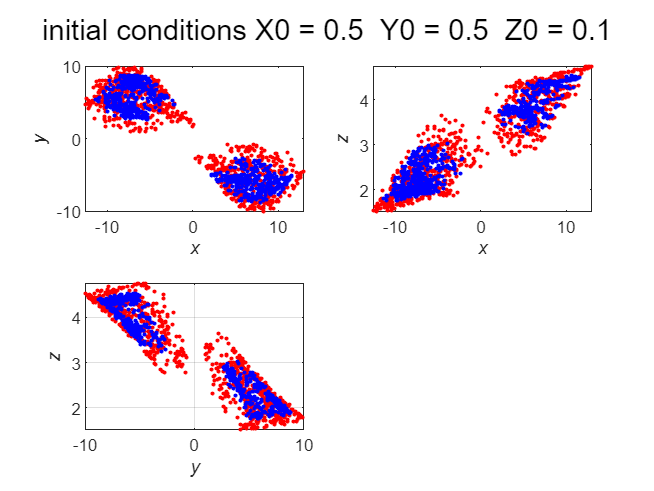

% todo: 完成图像绘制函数（输入为f1_FPGA f1_out）
% step: 3 图像绘制
draw_pic(figstart,f1_FPGA,MATLAB_f1_out,f1_x0);

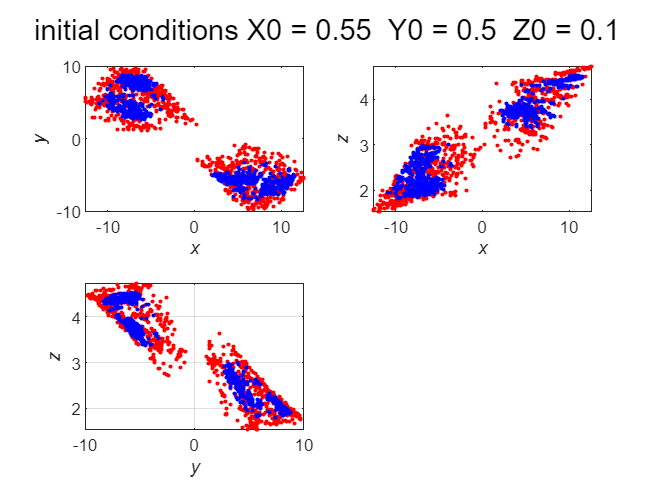

draw_pic(figstart,f2_FPGA,MATLAB_f2_out,f2_x0);

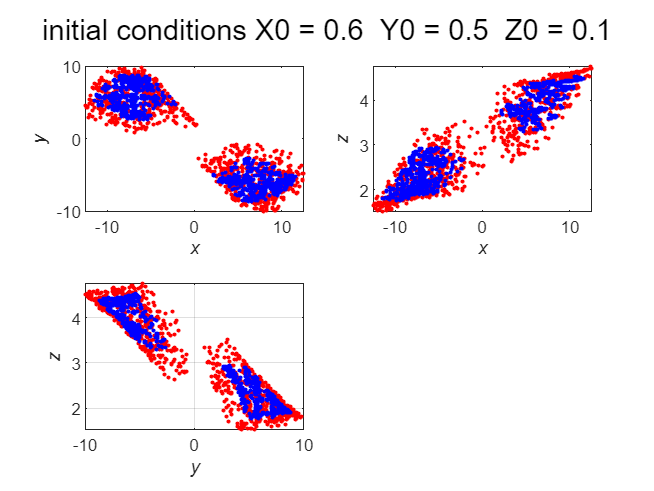

draw_pic(figstart,f3_FPGA,MATLAB_f3_out,f3_x0);

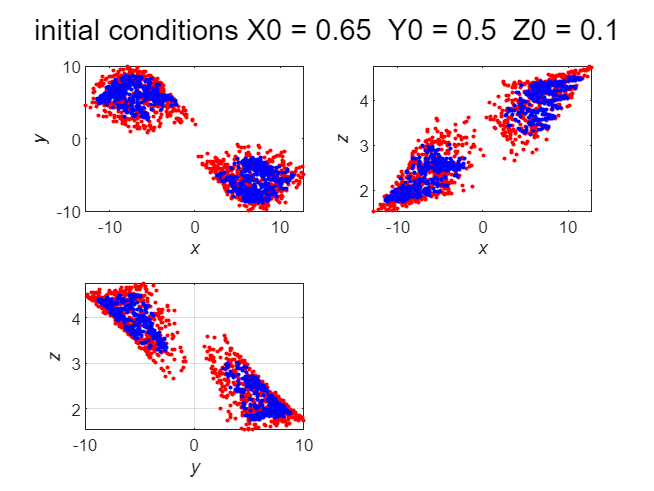

draw_pic(figstart,f4_FPGA,MATLAB_f4_out,f4_x0);

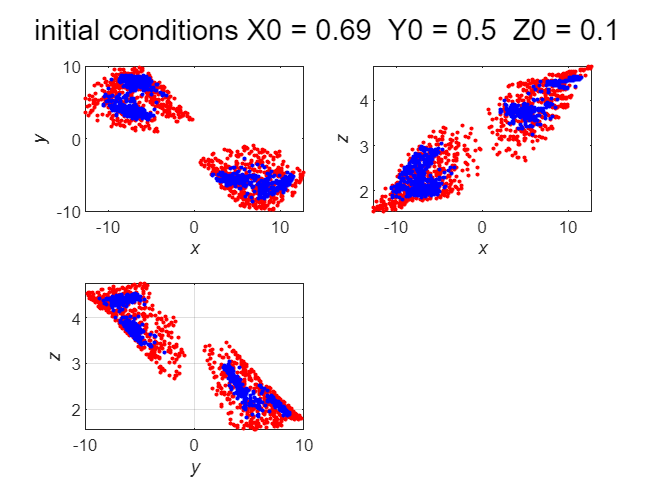

draw_pic(figstart,f5_FPGA,MATLAB_f5_out,f5_x0);

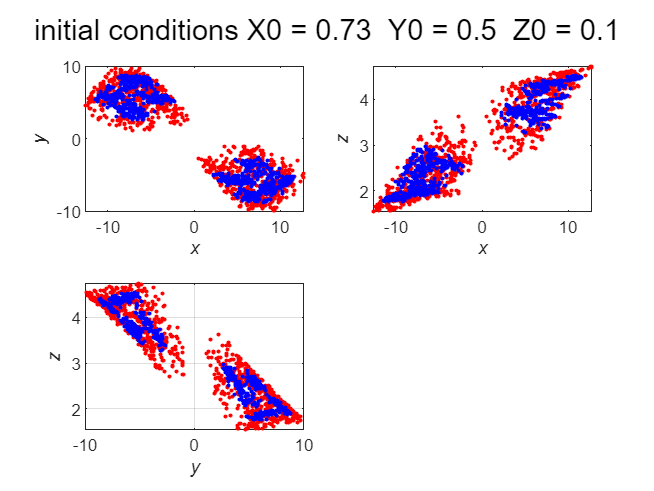

draw_pic(figstart,f6_FPGA,MATLAB_f6_out,f6_x0);

## 相关函数定义

function Y = ChaosMapInteg(parameter,tspan,X0)
%  Matlab计算混沌序列的方程
    N = length(tspan);
    M = length(X0);
    Y = zeros(M,N);
    Y(:,1)=X0 ; 
    for i = 2:N
        Y(:,i) = ChaosModel(Y(:,i-1),parameter);
    end
end


% 混沌模型
function Xstate = ChaosModel(xstate,parameter)
   % 根据不同的模型输入不同的数据
    ux = xstate(1);
    uy = xstate(2);    
    uz = xstate(3);    

    %模型已知的参数
    ua  = parameter(1);
    ub  = parameter(2);
    uc  = parameter(3);
    ud  = parameter(4);
    ue  = parameter(5);        
    utao  = parameter(6);
    uk0 = parameter(7);
    uk1 = parameter(8);
    uk2 = parameter(9);

    % 系统
     ux1 = ua*uy+uc*sin(ue*(uk0+uk1*uz+uk2*uz*uz)*uy);
     uy1 = ub*ux+ud*uy*cos(uz);
     uz1 = uz+utao*uy;
     %返回结果
    Xstate = [ux1;uy1;uz1] ; 
end


% FPGA输出的64位浮点txt文件转化为十进制的三维数组的函数
function fx_FPGA = float64_to_dec(tspan,f_x,f_y,f_z)
    % 分别读取x y z对应的txt文件
    fx_FPGA = zeros(3,length(tspan));

    xn1_data = fscanf(f_x,'%s',[64,length(tspan)]);
    fclose(f_x);
    xn1_data = xn1_data';

    yn1_data = fscanf(f_y,'%s',[64,length(tspan)]);
    fclose(f_y);
    yn1_data = yn1_data';

    zn1_data = fscanf(f_z,'%s',[64,length(tspan)]);
    fclose(f_z);
    zn1_data = zn1_data';
    
    % for循环将文件内容转化为10进制，并打包为三维数组
    for n1_i = 1:length(tspan)
        % 暂存
        xn1_data_buff = xn1_data(n1_i,:);
        yn1_data_buff = yn1_data(n1_i,:);
        zn1_data_buff = zn1_data(n1_i,:);
        % 转化为10进制
        fx_FPGA(1,n1_i) = BinaryFloat2DecFloat_64(xn1_data_buff);
        fx_FPGA(2,n1_i) = BinaryFloat2DecFloat_64(yn1_data_buff);
        fx_FPGA(3,n1_i) = BinaryFloat2DecFloat_64(zn1_data_buff);
    end
end


% 64位浮点数转化为十进制的函数
function dec_num = BinaryFloat2DecFloat_64(BinStr)
    % 拆分符号位、指数位以及数字位
    sign = str2num(BinStr(1));
    exponent = bin2dec(BinStr(2:12));
    for i = 1:52
        mantissa_bin(i) = BinStr(i+12);
    end
    mantissa = 0;
    for i = 1:52
        mantissa = mantissa + (str2num(mantissa_bin(i)))*(2^(-i));
    end
    mantissa = mantissa + 1;
    % 按照float64重组
    dec_num = ((-1)^(sign)) * mantissa * 2^(exponent-1023);
end


% 图像绘制函数
function draw_pic(figstart,f_FPGA,f_out,X0)
    figure();
    % 分别绘制x-y x-z y-z图像
    subplot(2,2,1);
    plot(f_FPGA(1,figstart:end),f_FPGA(2,figstart:end),'r.' ,f_out(1,figstart:end),f_out(2,figstart:end),'b.','linewidth',1);
    xlabel('\itx'); ylabel('\ity');
    subplot(2,2,2);
    plot(f_FPGA(1,figstart:end),f_FPGA(3,figstart:end),'r.',f_out(1,figstart:end),f_out(3,figstart:end),'b.','linewidth',1);
    xlabel('\itx'); ylabel('\itz');
    subplot(2,2,3);
    plot(f_FPGA(2,figstart:end),f_FPGA(3,figstart:end),'r.',f_out(2,figstart:end),f_out(3,figstart:end),'b.','linewidth',1);
    xlabel('\ity'); ylabel('\itz');
    % 添加总标题
    titleStr = ['initial conditions X0 = ', num2str(X0(1)), '  Y0 = ', num2str(X0(2)) , '  Z0 = ', num2str(X0(3))];
    sgtitle(titleStr);
    grid on;
end